Problema 3 Pablo Marcos Parra

a) Solución exacta

format short
syms x
y1=dsolve('D2y+2*Dy=x^3','y(0)=2','Dy(0)=1','x')

$$y1 = \frac{3\,x^{2}}{8}-\frac{11\,{\mathrm{e}}^{-2\,x}}{16}-\frac{3\,x}{8}-\frac{x^{3}}{4}+\frac{x^{4}}{8}+\frac{43}{16}$$

simplify(y1)

$$ans = \frac{3\,x^{2}}{8}-\frac{11\,{\mathrm{e}}^{-2\,x}}{16}-\frac{3\,x}{8}-\frac{x^{3}}{4}+\frac{x^{4}}{8}+\frac{43}{16}$$

b)Euler explicito

Sol =          0    2.0000
    0.1000    2.2000
    0.2000    2.4091
    0.3000    2.6255
    0.4000    2.8481
    0.5000    3.0757
    0.6000    3.3074
    0.7000    3.5427
    0.8000    3.7810
    0.9000    4.0222


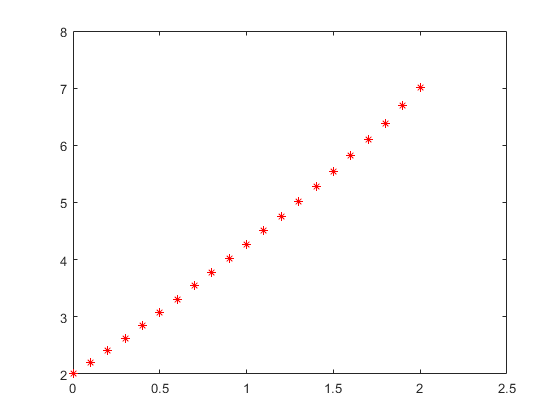

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


y =     2.0000    2.2000    2.4091    2.6255    2.8481    3.0757    3.3074    3.5427    3.7810    4.0222    4.2662    4.5132    4.7635    5.0177    5.2767    5.5417    5.8141    6.0955    6.3882    6.6945    7.0173


a=0;b=2;h=0.1;y0=2;  %función
f = @(x,y) (3*x^2)/8 - (11*exp((-2*x)))/16 - (3*x)/8 - x^3/4 + x^4/8 + sym(43/16);
[x,y]=odeEuler(f,a,b,h,y0)

c)Runge-Kutta h=0.1

a=0;b=2;h=0.1;y0=2;
[x,y]=RK3(f,a,b,h,y0);

d) Tabla con los resultados

e)Gráfico con las soluciones obtenidas

i)Funciones usadas

function [x,y] = odeEuler(ODE,a,b,h,y0)
N=(b-a)/h;      % número de pasos
x=zeros(1,N+1);
y=zeros(1,N+1);

x(1)=a; y(1)=y0;    % valores iniciales

for i=1:N
    x(i+1)=x(i)+h;
    y(i+1)=y(i)+ODE(x(i),y(i))*h;
end
Sol=[x',y']
plot(x,y,'*r')


end
%runge-kutta orden 3
function [x,y]=RK3(ODE,a,b,h,yini)
x(1)=a;
y(1)=yini;
N=(b-a)/h;
for i=1:N
    x(i+1)=x(i)+h;
    K1=ODE(x(i),y(i));
    xm=x(i)+h/2;
    yK1=y(i)+K1*h/2;
    K2=ODE(xm,yK1);
    yK2=y(i)+K2*h/2;
    K3=ODE(xm,yK2);;
    y(i+1)=y(i)+(K1+4*K2+2*K3)*h/6;
end
end